# reprodue Zhang 2026 for paper review

## get data

bp=illustris.set_env(100);

*** cosmolgy for TNG100 has been set: *** 
hub= 0.677 
Omm = 0.31 
Oml= 0.69 
Omb= 0.0486 
***  *** 
*** You are now analyzing the TNG100 Simulation. ENJOY!  *** 


snap=99; 

illustris.utils.set_illUnits(snap);

global illUnits;
global DEFAULT_MATFILE_DIR
global simDisplayName
global cosmoStruct


[subs, fofs, subsInfo]=illustris.loadFofSub(snap);
R200c=double(fofs.Group_R_Crit200(subsInfo.hostFof+1));


load('C:\Users\eladz\Documents\workProjects\matlab_scripts\IllustrisTNG\matFiles\gasMasses_zhang2026_snp99_TNG100.mat')

massThresh=5e9; % threshold for *stellar* mass
massAllGals=illustris.utils.get_stellar_mass(subs,'gal');
maskBase=illustris.infrastructure.generateMask('subs',subs','fofs',fofs,'mass',massThresh,'snap',snap,'centrals');

mdm=subs.SubhaloMassType(illustris.partTypeNum('dm')+1,:).*illUnits.massUnit;
mbh1=subs.SubhaloMassType(illustris.partTypeNum('bh')+1,:).*illUnits.massUnit;
mbh=subs.SubhaloBHMass.*illUnits.massUnit;
papMask=massAllGals>massThresh & subsInfo.isCentral & subs.SubhaloBHMass>0;% & subs.SubhaloMassType(1,:)>0;

fprintf('Number of gals in base mask : %i \n',sum(maskBase & subs.SubhaloBHMass>0))

Number of gals in base mask : 5090 


fprintf('Number of gals in paper mask : %i \n',sum(papMask))

Number of gals in paper mask : 5090 


mst=massAllGals(papMask);
mdm=mdm(papMask);
mbh=mbh(papMask);

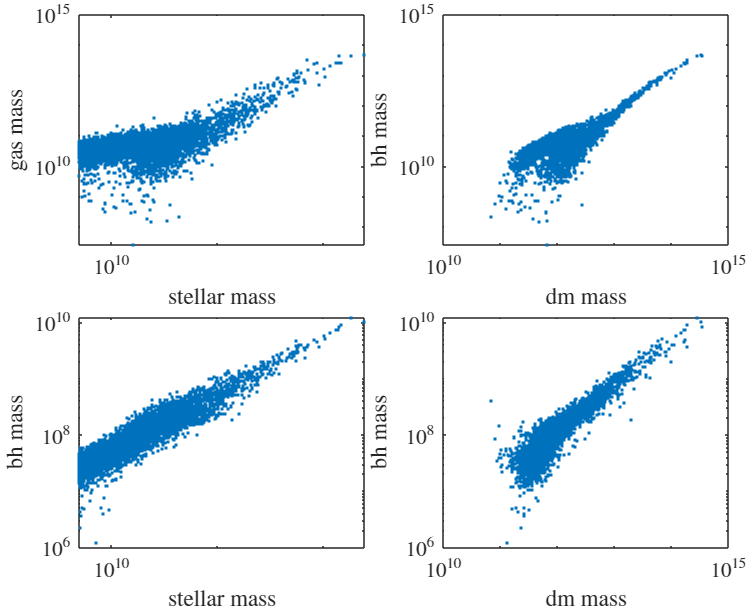

myFigure;
tt=tiledlayout(2,2,'TileSpacing','tight','Padding','tight');

nexttile
loglog(mst,gasMass.tot(3,:),'.');
xlabelmine('stellar mass');
ylabelmine('gas mass');
myAxis;



nexttile
loglog(mdm,gasMass.tot(3,:),'.');
%hold on
%loglog(mdm,mbh1(papMask),'.');
xlabelmine('dm mass');
ylabelmine('bh mass');
myAxis;

nexttile
loglog(mst,mbh,'.');
xlabelmine('stellar mass');
ylabelmine('bh mass');
myAxis;

nexttile
loglog(mdm,mbh,'.');
%hold on
%loglog(mdm,mbh1(papMask),'.');
xlabelmine('dm mass');
ylabelmine('bh mass');
myAxis;

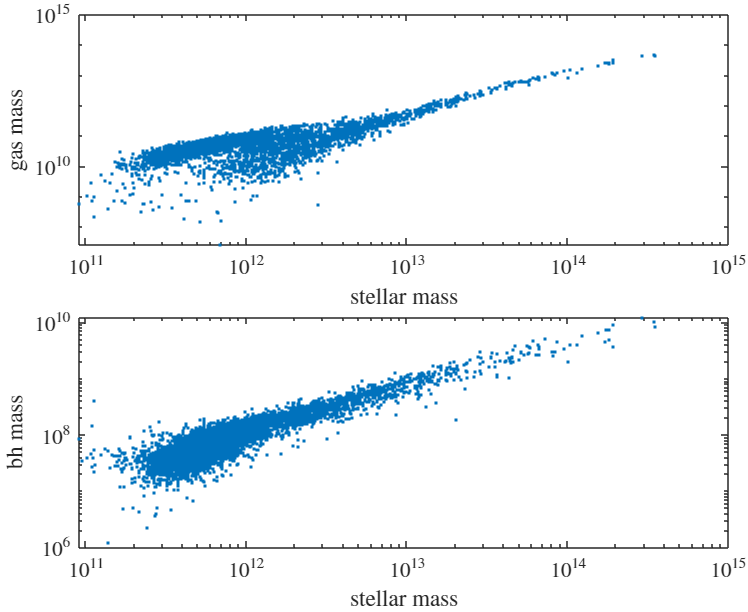

myFigure;
tt=tiledlayout(2,1,'TileSpacing','tight','Padding','tight');

nexttile
loglog(mst+mdm,gasMass.tot(3,:),'.');
xlabelmine('stellar mass');
ylabelmine('gas mass');
myAxis;
nexttile
loglog(mst+mdm,mbh,'.');
xlabelmine('stellar mass');
ylabelmine('bh mass');
myAxis;

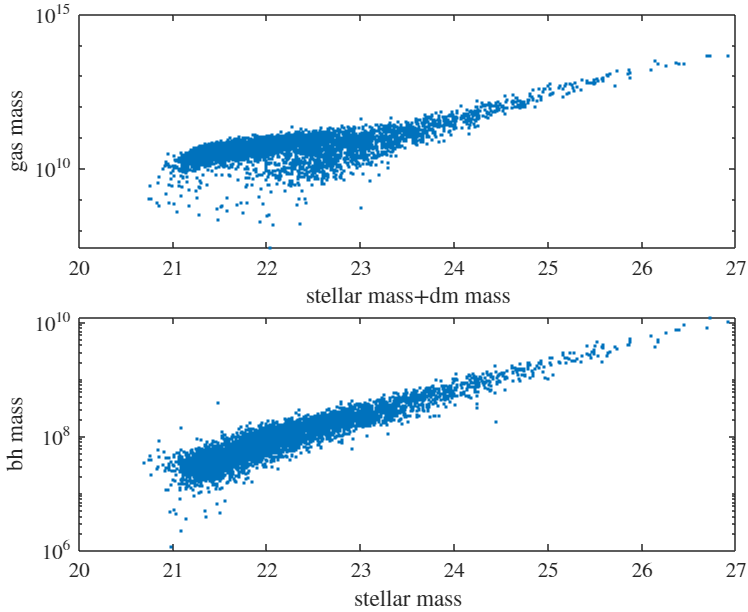


myFigure;

tt=tiledlayout(2,1,'TileSpacing','tight','Padding','tight');

nexttile
semilogy(log10(mst)+log10(mdm),gasMass.tot(3,:),'.');
xlabelmine('stellar mass+dm mass');
ylabelmine('gas mass');
myAxis;
nexttile
semilogy(log10(mst)+log10(mdm),mbh,'.');
xlabelmine('stellar mass');
ylabelmine('bh mass');
myAxis;

## examining the gas masses

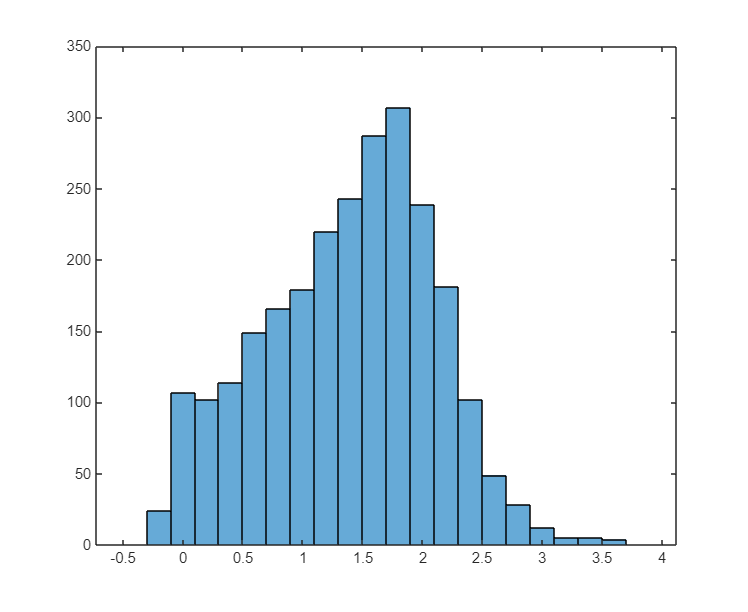

mb=9.4e5./cosmoStruct.hub;
myFigure;
histogram(log10(gasMass.cold(1,:)./mb),-0.5:0.2:4)


fprintf('no. of gals with more than 10 cold cells: %i, out of %i altogether',...
    sum(gasMass.cold(1,:)./mb>10), length(gasMass.cold(1,:)));

no. of gals with more than 10 cold cells: 1779, out of 5090 altogether


fprintf('no. of gals with more than 10 cool cells: %i, out of %i altogether',...
    sum(gasMass.cool(1,:)./mb>10), length(gasMass.cool(1,:)));

no. of gals with more than 10 cool cells: 4315, out of 5090 altogether


fprintf('no. of gals with more than 10 warm cells: %i, out of %i altogether',...
    sum(gasMass.warm(1,:)./mb>10), length(gasMass.warm(1,:)));

no. of gals with more than 10 warm cells: 2561, out of 5090 altogether


fprintf('no. of gals with more than 10 hot cells: %i, out of %i altogether',...
    sum(gasMass.hot(1,:)./mb>10), length(gasMass.hot(1,:)));

no. of gals with more than 10 hot cells: 1688, out of 5090 altogether

for k=1:3
    tots(k,:)=gasMass.cold(k,:)+gasMass.cool(k,:)+gasMass.warm(k,:)+gasMass.hot(k,:);
end


tag=["<0.03" "<0.15" "1" ">1"];


myFigure;
tt=tiledlayout(2,2,'Padding','loose','TileSpacing','loose');
for k=1:4

cgf=gasMass.cold(k,:)./(gasMass.tot(k,:)).*100;

nexttile;
histogram(cgf,0:2:100);
title(tag(k));
median(cgf(~isnan(cgf)))
end

ans = 0.1720

ans = 22.3586

ans = 5.6009

ans = 0

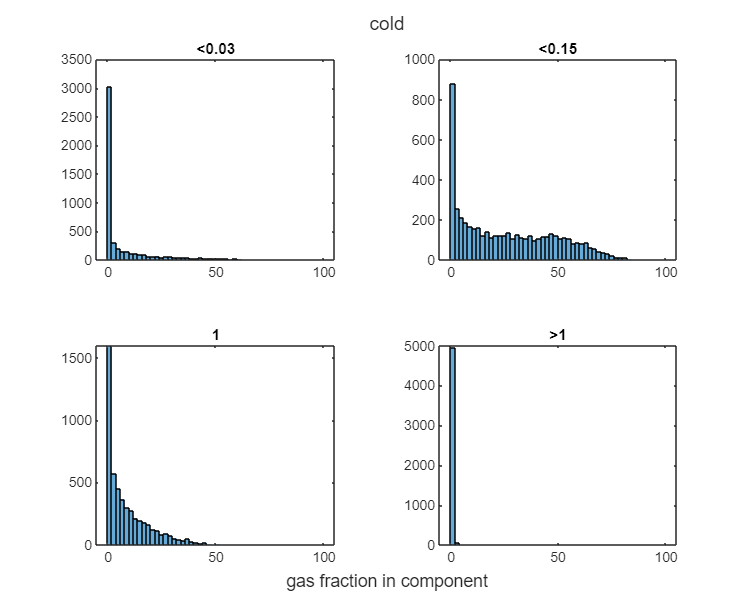

tt.Title.String='cold';
tt.XLabel.String='gas fraction in component';

myFigure;
tt=tiledlayout(2,2,'Padding','loose','TileSpacing','loose');
for k=1:4

cgf=gasMass.cool(k,:)./(gasMass.tot(k,:)).*100;

nexttile;
histogram(cgf,0:2:100)
title(tag(k));
median(cgf(~isnan(cgf)))
end

ans = 78.9630

ans = 53.3840

ans = 29.1883

ans = 13.9174

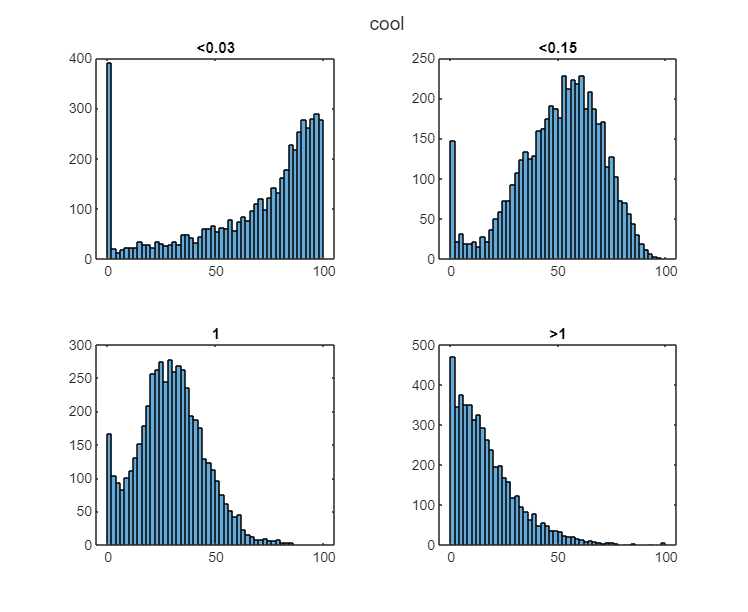

tt.Title.String='cool' ;

myFigure;
tt=tiledlayout(2,2,'Padding','loose','TileSpacing','loose');
for k=1:4

cgf=gasMass.warm(k,:)./(gasMass.tot(k,:)).*100;

nexttile;
histogram(cgf,0:2:100)
title(tag(k));
median(cgf(~isnan(cgf)))
end

ans = 5.3895

ans = 8.0831

ans = 47.5161

ans = 80.2601

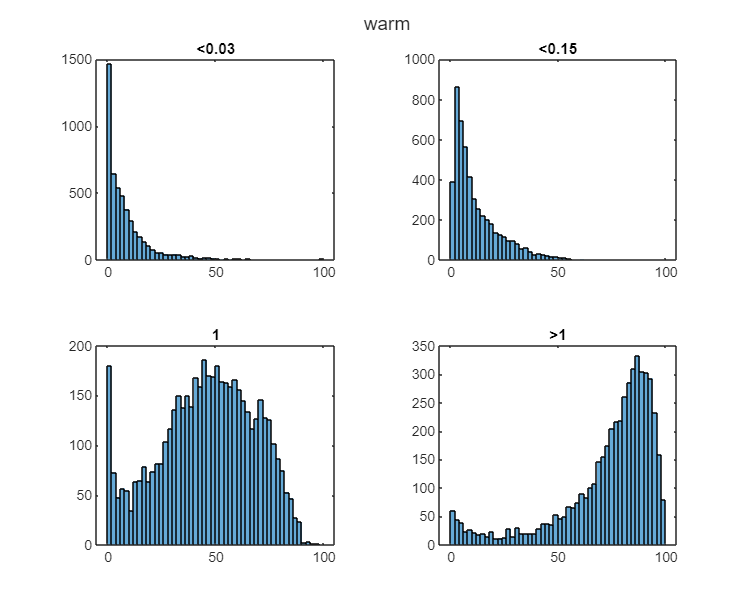

tt.Title.String='warm' ;

myFigure;
tt=tiledlayout(2,2,'Padding','loose','TileSpacing','loose');
for k=1:4

cgf=gasMass.hot(k,:)./(gasMass.tot(k,:)).*100;

nexttile;
histogram(cgf,0:2:100)
title(tag(k));
median(cgf(~isnan(cgf)))
end

ans = 1.8857

ans = 2.8294

ans = 1.9943

ans = 0

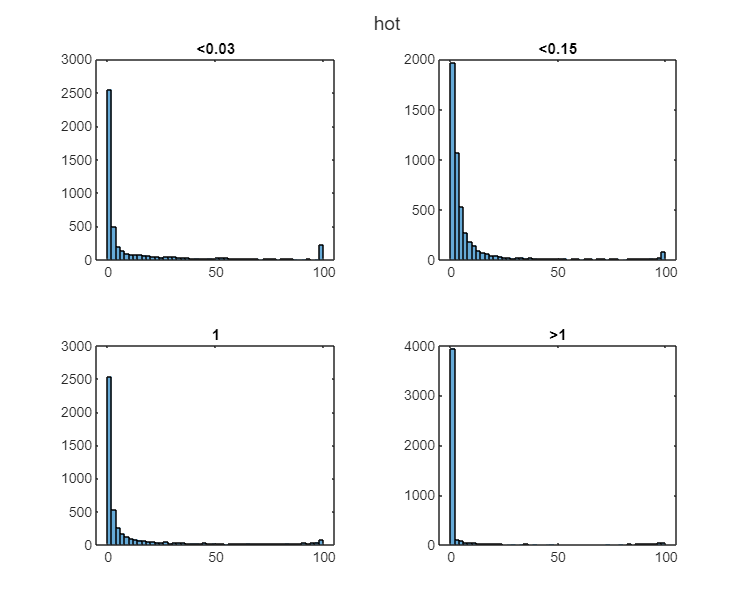

tt.Title.String='hot' ;


myFigure;
tt=tiledlayout(2,2,'Padding','loose','TileSpacing','loose');
for k=1:4

cgf=gasMass.count.cold(k,:);

nexttile;
histogram(log10(cgf+1));
title(tag(k));
round(nnz(gasMass.count.cold(k,:)>1 & gasMass.count.cold(k,:)<=10)./nnz(gasMass.count.cold(k,:)>0)*100)

end

ans = 24

ans = 4

ans = 2

ans = 28

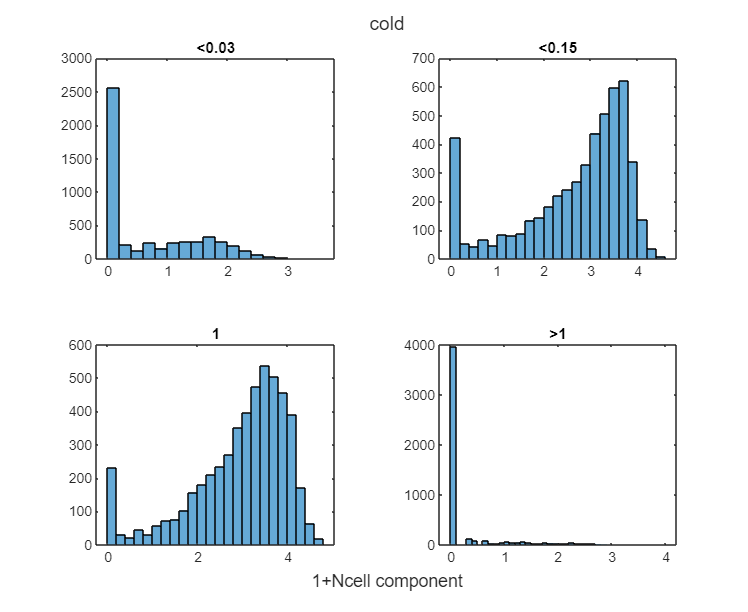

tt.Title.String='cold';
tt.XLabel.String='1+Ncell component';

myFigure;
tt=tiledlayout(2,2,'Padding','loose','TileSpacing','loose');
for k=1:4

cgf=gasMass.count.cool(k,:);

nexttile;
histogram(log10(cgf+1));
title(tag(k));
round(nnz(gasMass.count.cool(k,:)>1 & gasMass.count.cool(k,:)<=10)./nnz(gasMass.count.cool(k,:)>0)*100)

end

ans = 7

ans = 1

ans = 0

ans = 1

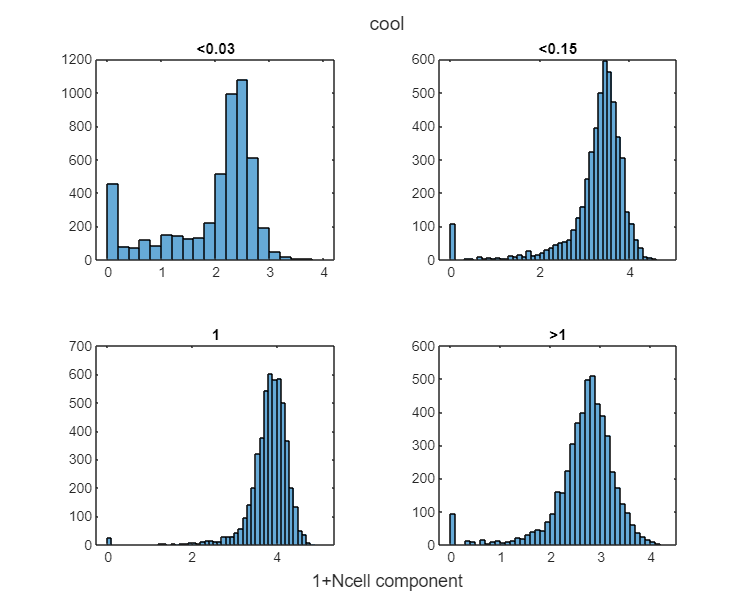

tt.Title.String='cool' ;
tt.XLabel.String='1+Ncell component';

myFigure;
tt=tiledlayout(2,2,'Padding','loose','TileSpacing','loose');
for k=1:4

cgf=gasMass.count.warm(k,:);
nexttile;
histogram(log10(cgf+1));
title(tag(k));
round(nnz(gasMass.count.warm(k,:)>1 & gasMass.count.warm(k,:)<=10)./nnz(gasMass.count.warm(k,:)>0)*100)

end

ans = 39

ans = 1

ans = 0

ans = 0

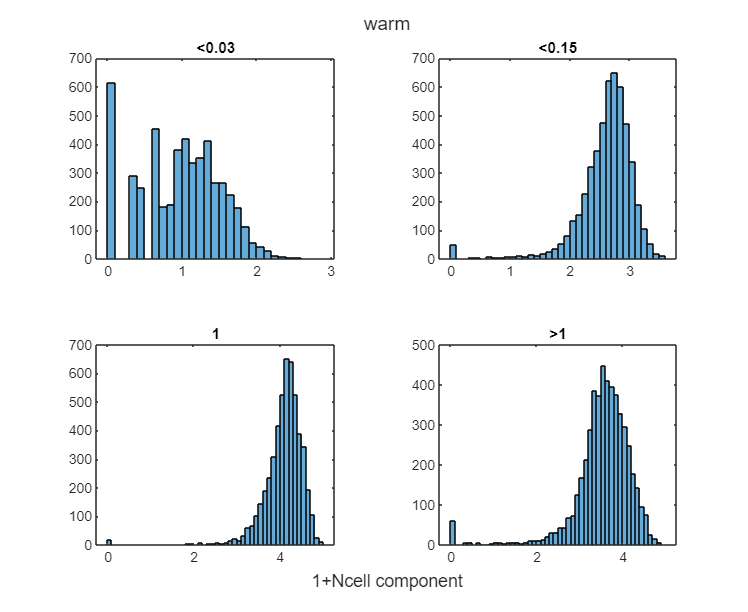

tt.Title.String='warm' ;
tt.XLabel.String='1+Ncell component';

myFigure;
tt=tiledlayout(2,2,'Padding','loose','TileSpacing','loose');
for k=1:4

cgf=gasMass.count.hot(k,:);

nexttile;
histogram(log10(cgf+1));
title(tag(k));
round(nnz(gasMass.count.hot(k,:)>1 & gasMass.count.hot(k,:)<=10)./nnz(gasMass.count.hot(k,:)>0)*100)
end

ans = 47

ans = 1

ans = 1

ans = 9

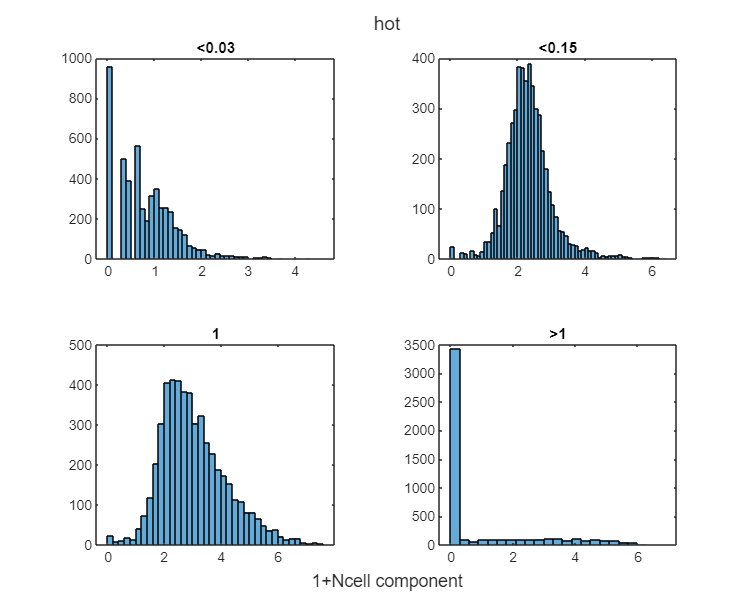

tt.Title.String='hot' ;
tt.XLabel.String='1+Ncell component';